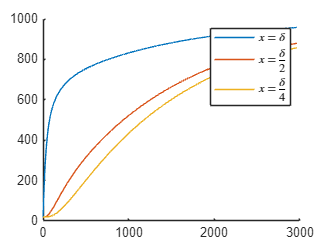

clear;clc;
setting;
% 第二问数值解
t_s_num = num_solu(Fo,Bi,n,dtau,tau,t_0,t_f);
t_d = t_s_num(:,n);
t_2d= t_s_num(:,3);
t_4d= t_s_num(:,2);
figure("Name","(2)数值")
hold on
plot(t_d)
plot(t_2d)
plot(t_4d)
hold off
legend("$x=\delta$","$x=\frac{\delta}{2}$","$x=\frac{\delta}{4}$","Interpreter","latex")

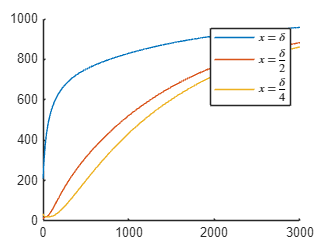

clear;clc;
setting;
% 第二问解析解
for i = 1:3000
    Fo = a*i/(delta^2);
    t_d(i) = t_f+(t_0-t_f)*analytical_solu(1,Fo,Bi);
    t_2d(i)= t_f+(t_0-t_f)*analytical_solu(0.5,Fo,Bi);
    t_4d(i)= t_f+(t_0-t_f)*analytical_solu(0.25,Fo,Bi);
end
figure("Name","(2)解析")
hold on
plot(t_d)
plot(t_2d)
plot(t_4d)
hold off
legend("$x=\delta$","$x=\frac{\delta}{2}$","$x=\frac{\delta}{4}$","Interpreter","latex")

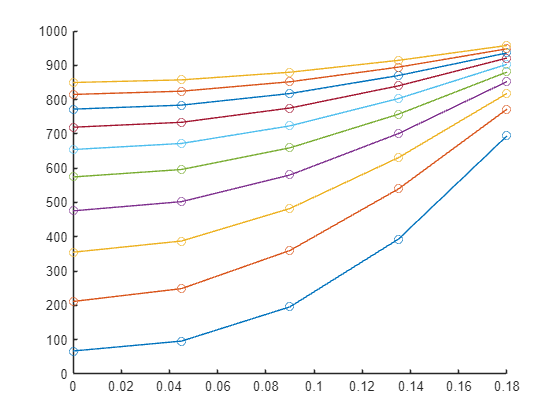

clear;clc;
setting;
%第三问数值解
t_s_num = num_solu(Fo,Bi,n,dtau,tau,t_0,t_f);
figure("Name","(3)数值")
hold on
for i = 1:10
    t_s(i,:) = t_s_num(round(tau/dtau/10*i),:);
    plot(node_x, t_s(i,:),"o-")
end
hold off

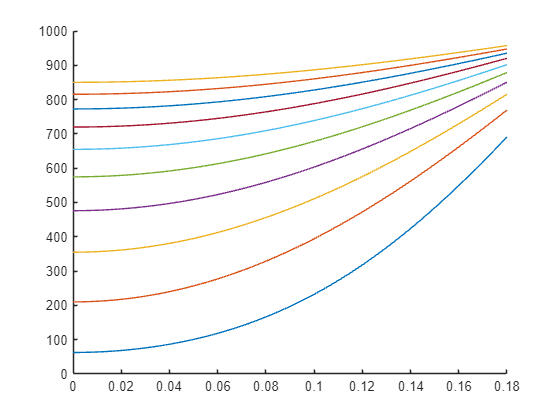

clear;clc;
setting;
%第三问解析解
n=100;% 节点数
dx = delta/(n-1);% 步长
node_x = 0:dx:delta-dx/2;
node_x(1)=0;
node_x(n)=delta;
node_eta=node_x/delta;
i=1;
for tt = tau/10: tau/10 : tau
    Fo = a*tt/(delta^2);
    for j = 1:length(node_eta)
        t_s(i,j) =  t_f+(t_0-t_f)*analytical_solu(node_eta(j),Fo,Bi);
    end
    i=i+1;
end
figure("Name","(3)解析")
hold on
for i = 1:10
    plot(node_x,t_s(i,:));
end
hold off;